%Fecha de actualización: 21/oct/2023
%V 0.0.1
%clc
%clear all

# Practica 004: Curso de MATLAB para ingeniería

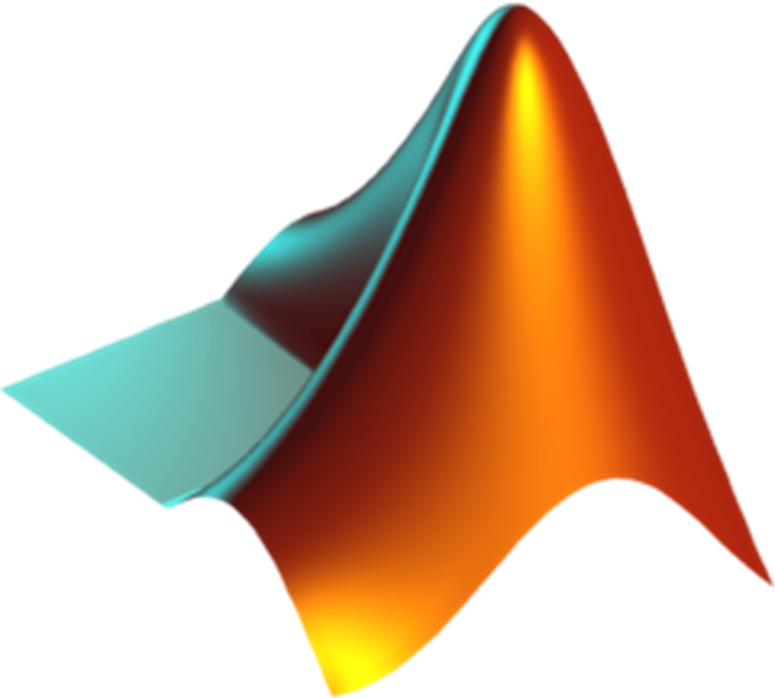

## **Declaración de gráficas**

El entorno de programación de matlab ofrece muchas posibilidades de realizar gráficas con los datos creados en estas. A un nivel general necesitas tener lo siguiente

1.- Declaración del dominio o rango que se utilizara para la gráfica

2.- Declaración de los valores dependientes de la gráfica

3.- Uso de los datos generados para crear la gráfica

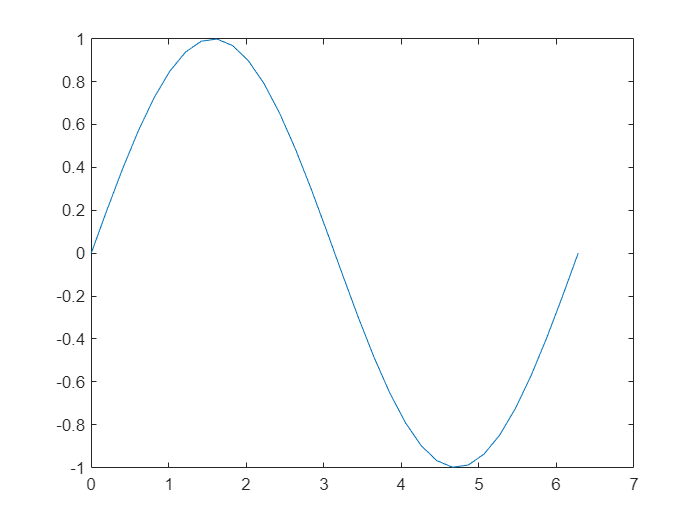

%Paso 1
x = linspace(0, 2*pi(),32);

%Paso 2
y1 = sin(x);
y2 = cos(x+pi()/2);

%paso3
plot(x,y1)

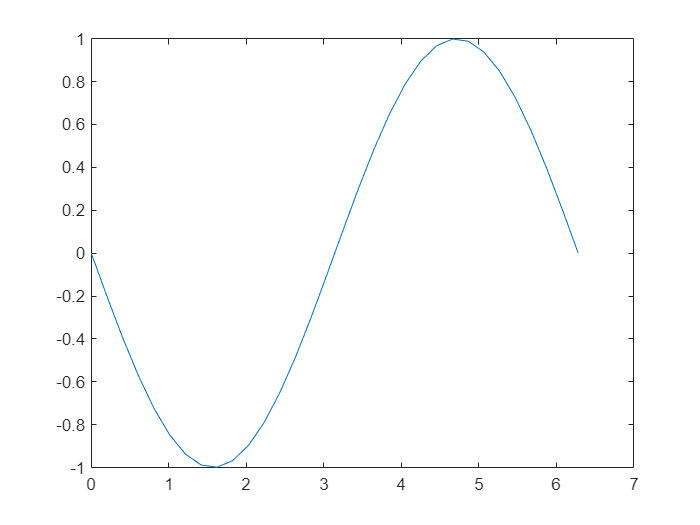

plot(x,y2)

### Color

En estos gráficos puedes modificar ciertos componentes de la gráfica mediante comandos especiales, por ejemplo modificar el color de la linea

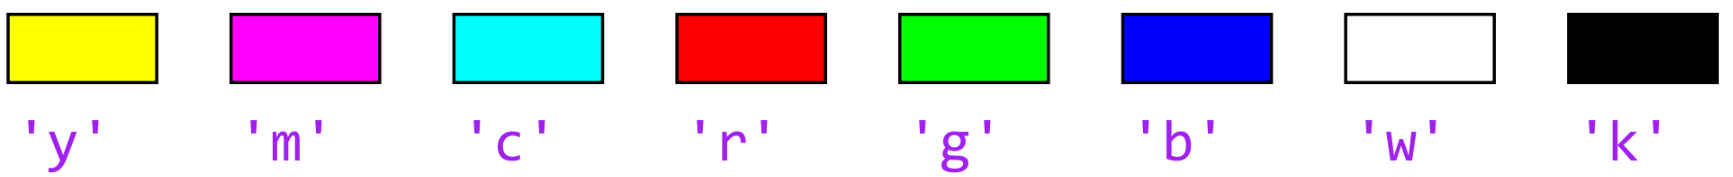

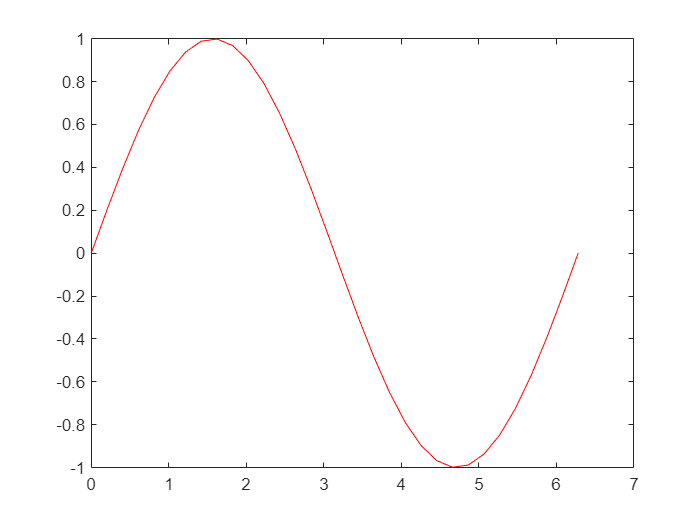

plot(x,y1,'Color','r')

### Estilo de marcadores

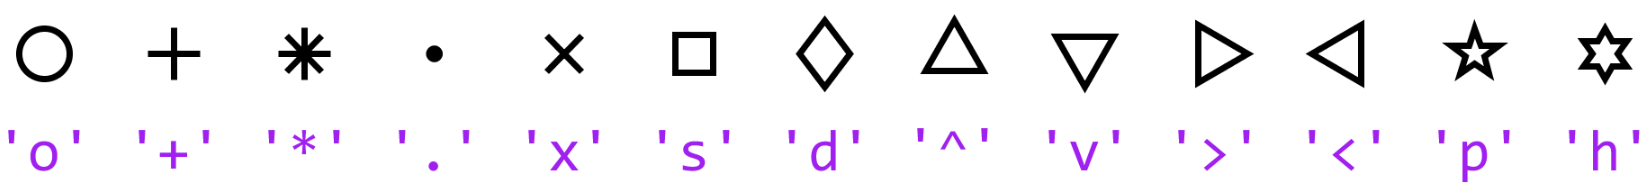

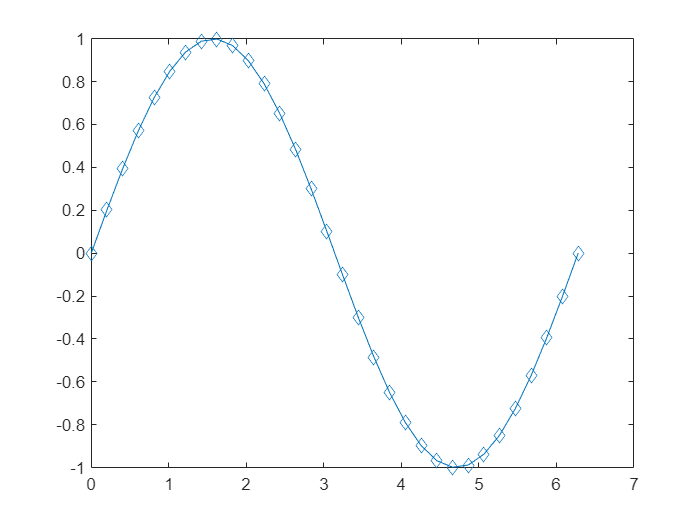

plot(x,y1,'marker','d')

### Determinacion de tamaños de marcadores

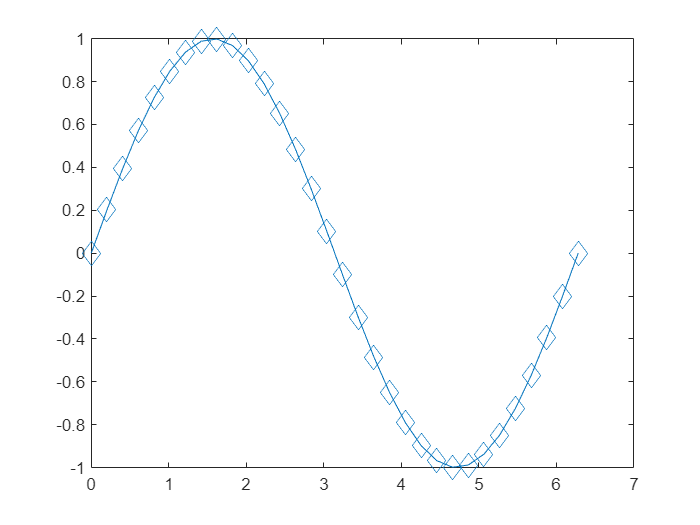

plot(x,y1,'markersize',10,'marker','d')

### Organizacion de la imagen

En Matlab puedes organizar una figura de la siguiente manera

#### Definicion del objeto figura

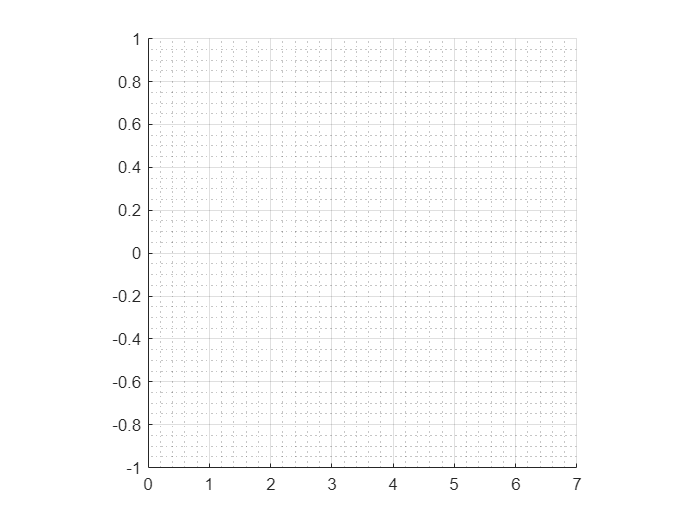

fig01=figure;
hold on
grid on

%Definition of axis
xMin=0; xMax=7;
yMin=-1; yMax=1;

axis([xMin xMax yMin yMax])
axis square;
%axis equal
grid minor

#### Definicion de datos para usar en el objeto figura

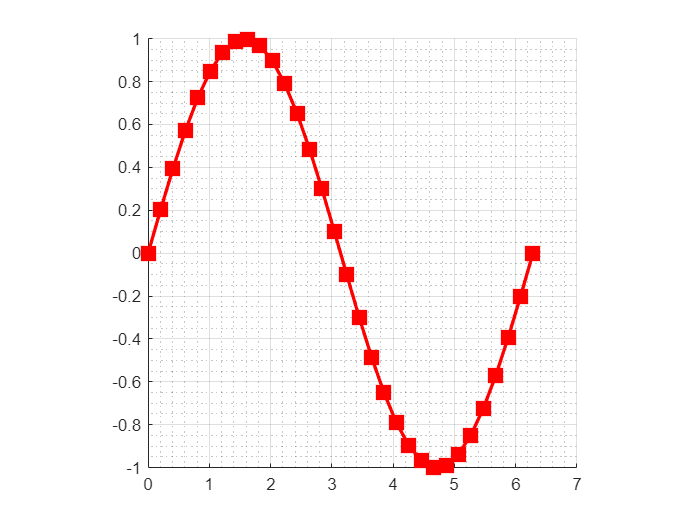

plot(x,y1,'rs-',...
              'LineWidth',2,...
              'MarkerSize',10,...
              'MarkerEdgeColor','r',...
              'MarkerFaceColor','r')

#### Definicion de propiedades del objeto figura

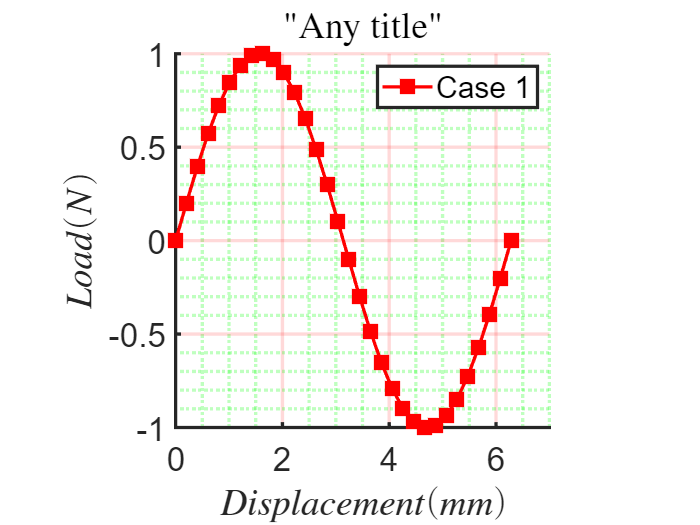

title('"Any title"'       ,'interpreter','latex')
ylabel('$Load (N)$'         ,'interpreter','latex')
xlabel('$Displacement (mm)$','interpreter','latex')
legend('Case 1')
%%
%Fancy colors
set(gca,'FontSize'       ,20,...
        'MinorGridColor' ,'g',...
        'GridColor'      ,'r',...
        'Xgrid'          ,'on',...
        'Ygrid'          ,'on',...
        'LineWidth'      ,2)
hold off

Existen diversos tipos de gráficos que puedes agregar en MATLAB, por ello te invito a revisar la documentacion en el siguiente enlace [MATLAB plot Gallery](https://la.mathworks.com/products/matlab/plot-gallery.html) para que visualices todas las posibilidades que ofrece el programa